# Statistics of Voting  - part 2

In the CJF project, we based the classification on the total sum of votes from 20 independent inspectors. We want to assess the robustness of this method, specifically the number of inspectors by using some statistical tests.

We can use the hypergeometric distribution to find how likely a score would be using a sub-sample 

## sub-sampling from 20 votes

NN=200;
KK=0.8*NN;
thresh=floor(KK/NN*100)/100;

nn=10:10:60;
%kk=thresh.*nn


h=[];
for i=1:length(nn)
    
    %kk=nn(i)-(NN-KK):min(nn(i),KK)
    nrm=nchoosek(NN,nn(i));
    
    kk=1:min(nn(i),KK)-1;
    pp2=[];
    for j=1:length(kk)
        try
            pp2(j)=nchoosek(KK,kk(j))*nchoosek(NN-KK,nn(i)-kk(j))/nrm;
        catch
            %fprintf('nn=%i, kk=%i \n',nn(i),kk(j));
        end
        
    end
    hg(i).pdf=pp2;
    hg(i).kk=kk;
    hg(i).nn=nn(i);
    hg(i).cdf=cumtrapz(kk,pp2);
    %h(i)=plot(kk./nn(i),pp2.*nn(i),'-o','DisplayName',['nn=' num2str(nn(i))]);
    %if i==1;hold on;end
    
end

%legend(h,'location','best')



% compare to binomial distribution 
nSample=nn;%[5:5:35 40:10:70];
eta=(0:0.0001:1)';
pdf=zeros(length(eta),length(nSample));
cpdf=zeros(length(eta),length(nSample));
xh=zeros(length(nSample),2);
score=0.8;
jMean=[];
jSigma=[];
peak=[];
xhalf=[];

for i=1:length(nSample)
    n=nSample(i);
    k=round(score*n);
    
    %pp=nchoosek(n,k).*eta.^k.*(1-eta).^(n-k);
    pp=eta.^k.*(1-eta).^(n-k);
    nnrm=1./trapz(eta,pp);
    pdf(:,i)=nnrm.*pp';
    
    
    % find fwhm
    
    [mx,ix]=max(pdf(:,i));
    halfMax=0.5.*(mx-min(pdf(:,i)));
    peak(i)=eta(ix);
    
    
    [mx,ix]=max(pdf(:,i));
    halfMax=0.5.*(mx-min(pdf(:,i)));
    
    if ix>1
        xh(i,1)=interp1(pdf(1:ix,i),eta(1:ix),halfMax);
    else
        xh(i,1)=eta(1);
    end
    
    if ix~=length(eta)
        xh(i,2)=interp1(pdf(ix:end,i),eta(ix:end),halfMax);
    else
        xh(i,2)=eta(end);
    end
    
    cpdf(:,i)=cumtrapz(eta,pdf(:,i));
    indd=find(cpdf(:,i)<0.5,1,'last');
    xhalf(i)=interp1(cpdf(indd-200:indd+200,i),eta(indd-200:indd+200),0.5);
    
    
    
    jMean(i)=trapz(eta,eta.*pdf(:,i));
    jmean2=trapz(eta,eta.^2.*pdf(:,i));
    %mean22=sqrt(trapz(eta,(eta-jMean).^2.*pdf))
    jSigma(i)=sqrt(jmean2-jMean(i).^2);
    
    
end
fwhm=diff(xh,1,2);


## plot distribution

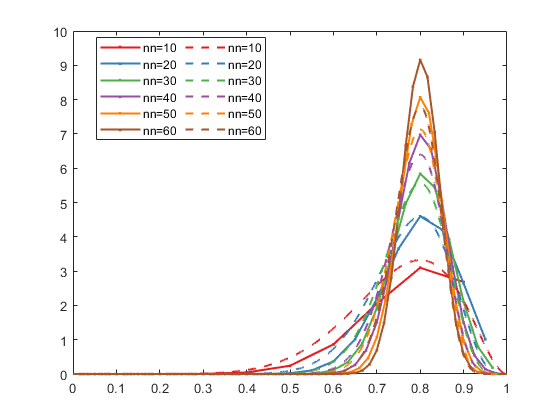

colors=brewermap(8,'Set1');
colors=colors([1:5 7:8],:);
figure
h=[];
for i=1:length(hg)
    h(i)=plot(hg(i).kk./hg(i).nn,hg(i).pdf.*hg(i).nn,'.-','linewidth',1.5,'color',colors(i,:),...
        'DisplayName',['nn=' num2str(hg(i).nn)]);
    
    if i==1;hold on;end
end
for j=1:length(nSample)
    h(i+j)=plot(eta,pdf(:,j),'--','color',colors(j,:),'linewidth',1.5,...
        'DisplayName',['nn=' num2str(nSample(j))]);
end
legend(h,'numcolumns',2,'location','best')

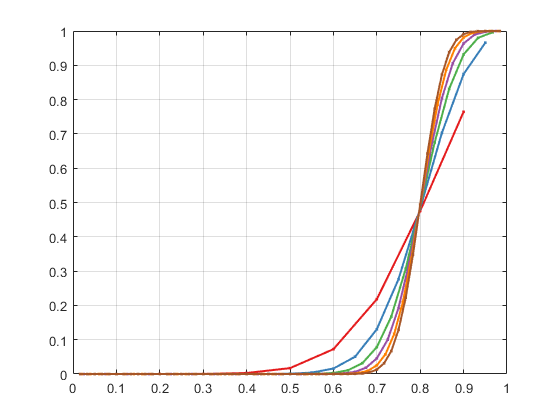



figure
h=[];
for i=1:length(hg)
    h(i)=plot(hg(i).kk./hg(i).nn,hg(i).cdf,'.-','linewidth',1.5,'color',colors(i,:),...
        'DisplayName',['nn=' num2str(hg(i).nn)]);
    
    if i==1;hold on;end
end
grid

## Map the subsampling of N=20

NN=20;
KK=0.8*NN;

mapp=-10.*ones(NN+1,NN);

nn=1:NN;

for i=1:length(nn)
    
    
    nrm=nchoosek(NN,nn(i));
    
    kk=0:min(nn(i),KK);
    %pp2=[];
    for j=1:length(kk)
        try
            mapp(j,i)=nchoosek(KK,kk(j))*nchoosek(NN-KK,nn(i)-kk(j))/nrm;
        catch
            %fprintf('nn=%i, kk=%i \n',nn(i),kk(j));
        end
        
    end
%     hg(i).pdf=pp2;
%     hg(i).kk=kk;
%     hg(i).nn=nn(i);
%     hg(i).cdf=cumtrapz(kk,pp2);
    %h(i)=plot(kk./nn(i),pp2.*nn(i),'-o','DisplayName',['nn=' num2str(nn(i))]);
    %if i==1;hold on;end
    
end

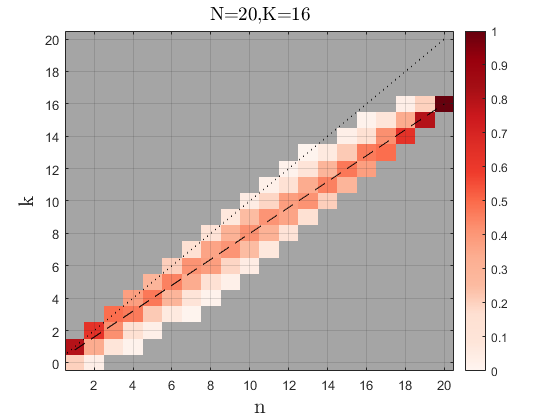

cmap=brewermap(256,'reds');
cmap(1,:)=[0.65 0.65 0.65];
figure
imagesc(nn,(0:20),mapp);
caxis([0 1])
colormap(cmap)
colorbar
set(gca,'YDir','normal')
hold on
plot([0 20],[0 20],':k')
plot(nn,nn.*0.8,'--k')
grid
ylabelmine('k');
xlabelmine('n');
titlemine('N=20,K=16');

## lets repeat for several scores

kkk =      1     4     8    10    12    16    19


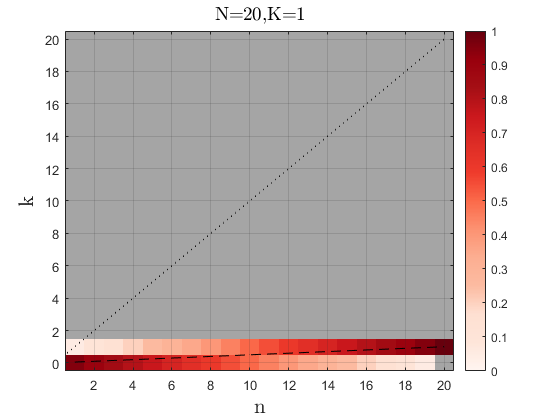

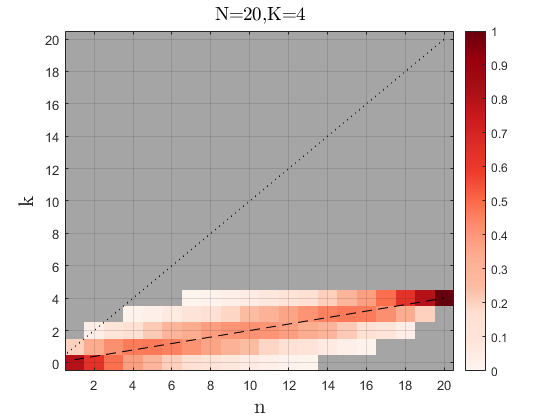

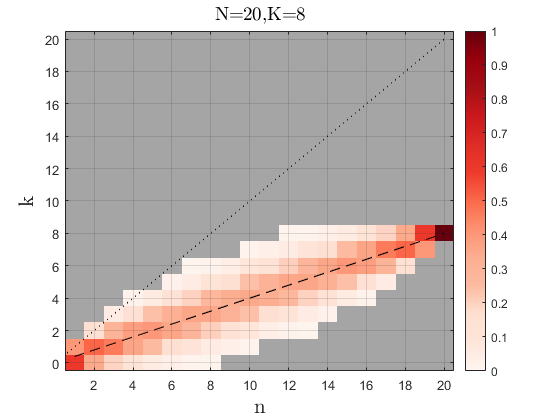

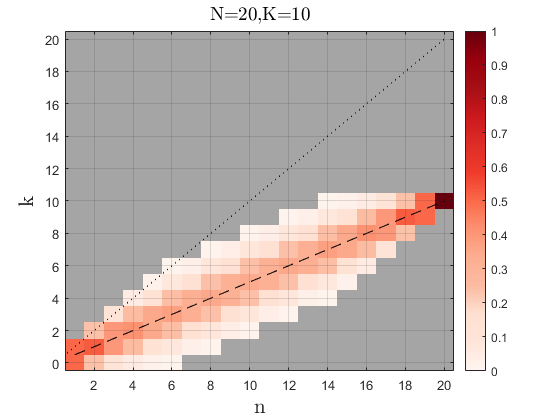

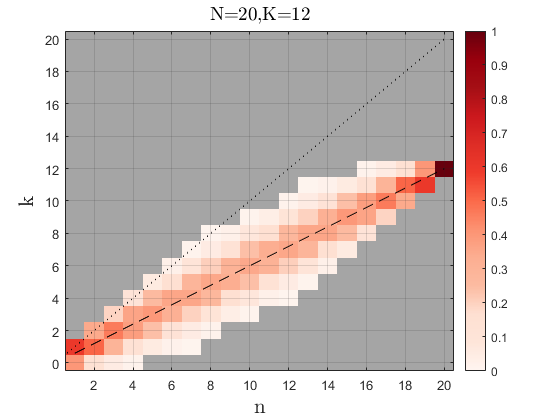

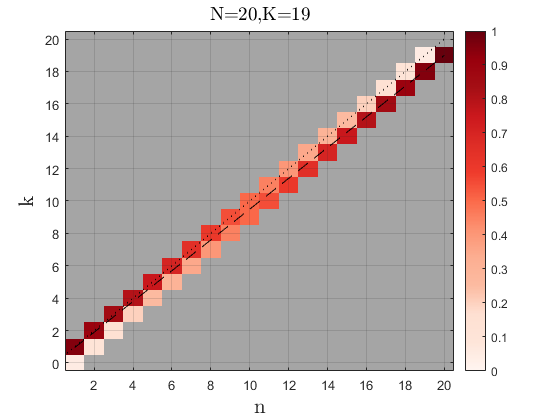

NN=20;


kkk=[0.05 0.2 0.4 0.5 0.6 0.8 0.95].*NN

cmap=brewermap(256,'reds');
cmap(1,:)=[0.65 0.65 0.65];

for k=1:length(kkk)
    KK=kkk(k);
    
    %mapp=-10.*ones(NN+1,NN);
    mapp=nan(NN+1,NN);
    nn=1:NN;
    
    for i=1:length(nn)
        nrm=nchoosek(NN,nn(i));
        
        kk=0:min(nn(i),KK);
        
        for j=1:length(kk)
            try
                mapp(j,i)=nchoosek(KK,kk(j))*nchoosek(NN-KK,nn(i)-kk(j))/nrm;
            catch
                %fprintf('nn=%i, kk=%i \n',nn(i),kk(j));
            end
            
        end
        
    end
    
    figure
    imagesc(nn,(0:20),mapp);
    caxis([0 1])
    colormap(cmap)
    colorbar
    set(gca,'YDir','normal')
    hold on
    plot([0 20],[0 20],':k')
    plot(nn,nn.*kkk(k)./NN,'--k')
    grid
    ylabelmine('k');
    xlabelmine('n');
    titlemine(['N=20,K=' num2str(kkk(k))]);
    
    if kkk(k)==10
        mapp10=mapp;
    end
end



## how do scores span for N=100 and n=20

NN=80;
nn=20;

KK=0:NN;
kk=0:nn;


mapp=nan(length(kk),length(KK));

nrm=nchoosek(NN,nn);

for i=1:length(KK)
    
    NNKK=NN-KK(i);
    
    for j=1:length(kk)
        try
            mapp(j,i)=nchoosek(KK(i),kk(j))*nchoosek(NNKK,nn-kk(j))/nrm;
        catch
            %fprintf('nn=%i, kk=%i \n',nn(i),kk(j));
        end
        
    end
    
end

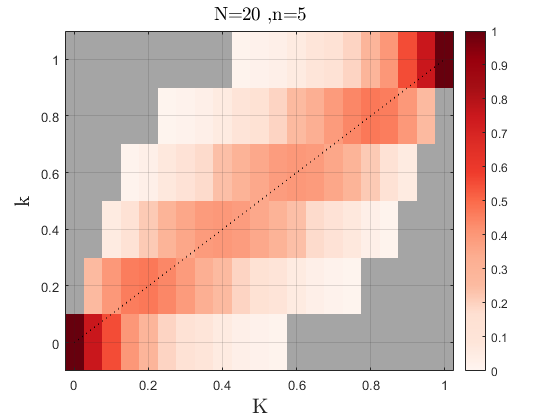

cmap=brewermap(256,'reds');
cmap(1,:)=[0.65 0.65 0.65];
figure
imagesc(KK./NN,kk./nn,mapp);
caxis([0 1])
colormap(cmap)
colorbar
set(gca,'YDir','normal')
hold on
plot([0 1],[0 1],':k')
%plot(nn,nn.*0.8,'--k')
grid
ylabelmine('k');
xlabelmine('K');
titlemine(['N=' num2str(NN) ' ,n=' num2str(nn)]);

## could this solve the U problem? 

NN=20;
nn=5;

KK=0:NN;
kk=0:nn;


mapp=nan(length(kk),length(KK));

nrm=nchoosek(NN,nn);

for i=1:length(KK)
    
    NNKK=NN-KK(i);
    
    for j=1:length(kk)
        try
            mapp(j,i)=nchoosek(KK(i),kk(j))*nchoosek(NNKK,nn-kk(j))/nrm;
        catch
            %fprintf('nn=%i, kk=%i \n',nn(i),kk(j));
        end
        
    end
    
end

cmap=brewermap(256,'reds');
cmap(1,:)=[0.65 0.65 0.65];
myFigure
imagesc(KK./NN,kk./nn,mapp);
caxis([0 1])
colormap(cmap)
colorbar
set(gca,'YDir','normal')
hold on
plot([0 1],[0 1],':k')
%plot(nn,nn.*0.8,'--k')
grid
ylabelmine('k');
xlabelmine('K');
titlemine(['N=' num2str(NN) ' ,n=' num2str(nn)]);

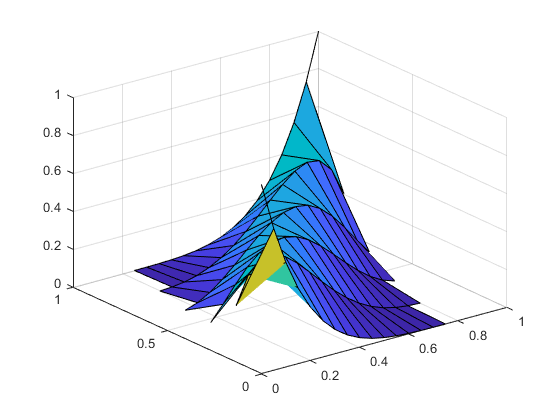


figure
surf(KK./NN,kk./nn,mapp)